依赖[统一实验分析作图v17.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

行为学重新作图

DataSetBas=TransferLearning.BasicTransferBehaviorDataSet;

SessionTableAL=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="声光水",Design="LightWater");
SessionTableAL.Group(:)="Transfer";
SessionTableLL=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="光声水",Design="LightWater");
SessionTableLL.Group(:)="Original";
SessionTableAA=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="声光水",Design="AudioWater");
SessionTableAA.Group(:)="Original";
SessionTableLA=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="光声水",Design="AudioWater");
SessionTableLA.Group(:)="Transfer";
SummaryL=UniExp.LearningSummarize([SessionTableAL;SessionTableLL]);SummaryA=UniExp.LearningSummarize([SessionTableAA;SessionTableLA]);

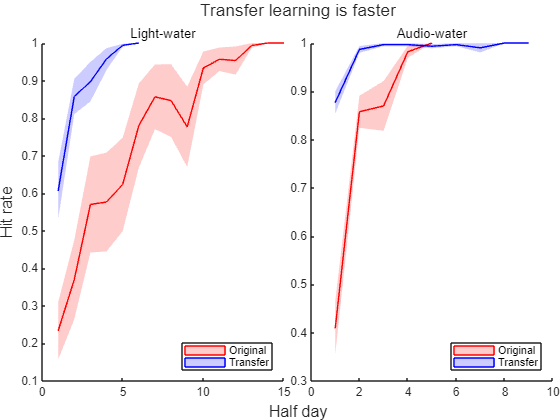

figure;
Colors=GlobalOptimization.ColorAllocate(2,[1,1,1;1,1,1]);
Layout=tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile;
Patches=MATLAB.Graphics.MultiShadowedLines(SummaryL.MeanCurve,SummaryL.SemCurve,EdgeColors=Colors(1:2,:));
legend(Patches,SummaryL.Group,Location='southeast');title('Light-water');
nexttile;
Patches=MATLAB.Graphics.MultiShadowedLines(SummaryA.MeanCurve,SummaryA.SemCurve,EdgeColors=Colors(1:2,:));
legend(Patches,SummaryA.Group,Location='southeast');title('Audio-water');
xlabel(Layout,'Half day');
ylabel(Layout,'Hit rate');
title(Layout,'Transfer learning is faster');

MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig1B.svg'),'-dsvg');

错误使用 validateHandleToPrint
无法导出。图窗必须包含图形。

出错 validate (第 17 行)
pj = validateHandleToPrint(pj); 

出错 print (第 67 行)
pj = validate( pj );